# Numerical Methods Assignment 2

Group XX

Noah Labuschagne S6621635

Danail Valov S5609895

Bashar Alsayed S4029291

**Instructions:**

- Submit the assignment by the deadline on Friday October 2 at 16:00 via Brightspace. All group members must be enrolled in the group before the assignment is submitted.

- **Submit two files: this .mlx file and an .pdf export of the same file. Save both files as NM_AS2_GroupX.mlx and NM_AS2_GroupX.pdf, replacing the X by your group number.**

- Ensure your group number, names and student numbers are at the top of the document.

- **Consult the course description for details** on the assignment, including information on the discussion and the generative AI policy.

- Include a statement on the ways in which you used generative AI, if any, in the box below. If you worked individually, ensure every group members writes their own statement.

- This type of MATLAB file is called a Live Code File Format (.mlx). It allows you to have all code in one place, and show code, generated figures, text, and equations all next to eachother. It is fairly self-explanatory, but this page and links within it provide some further explanation: [http://nl.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html.](http://nl.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html.) You are welcome to remove the text of the assignment or keep it and add in your solutions. 

## Generative AI statement

*Explain here how you used generative AI, if any, for this assignment. If you worked individually, use a separate statement for each group member.*

## Set-up (15 pts.)

The main functions you will use in this assignment are the following. Define the functions here and ensure you call them when solving the problems.

% Implementation of the Jacobi method

% Implementation of the Gauss-Seidel method

% Implementation of the composite midpoint rule
function [I] = composite_midpoint(f, f_prime2, fprime4, h)
I = f(h/2)*h + f_prime2(h/2)*((h^2)/24) + f_prime4(h/2)*((h^5)/1920);

% Implementation of the composite trapezoidal rule
function [I] = trapezoid(f, f_prime2, f_prime4, h)
I = (f(0) + f(h))*(h/2) - f_prime2(h/2)*((h^3)/12) + f_prime4(h/2)*((h^5)/480);

% Implementation of the composite Simpson's 1/3 rule
function [I] = simpson(f, h)
I = (h/6) * (f(0) + 4*f(h/2) + f(h));

## Problem 1: Numerical Methods for a loaded Bar (45 pts) 

A single straight bar has a cross-section that varies continuously along its axis according to a quadratic approximation. For the numerical analysis, the same bar is discretized into five axial elements joined at six nodes; these elements are not separate bars or physical steps. The left and right ends are fixed, and four concentrated axial forces are applied at the internal nodes. Positive force and positive displacement point to the right.

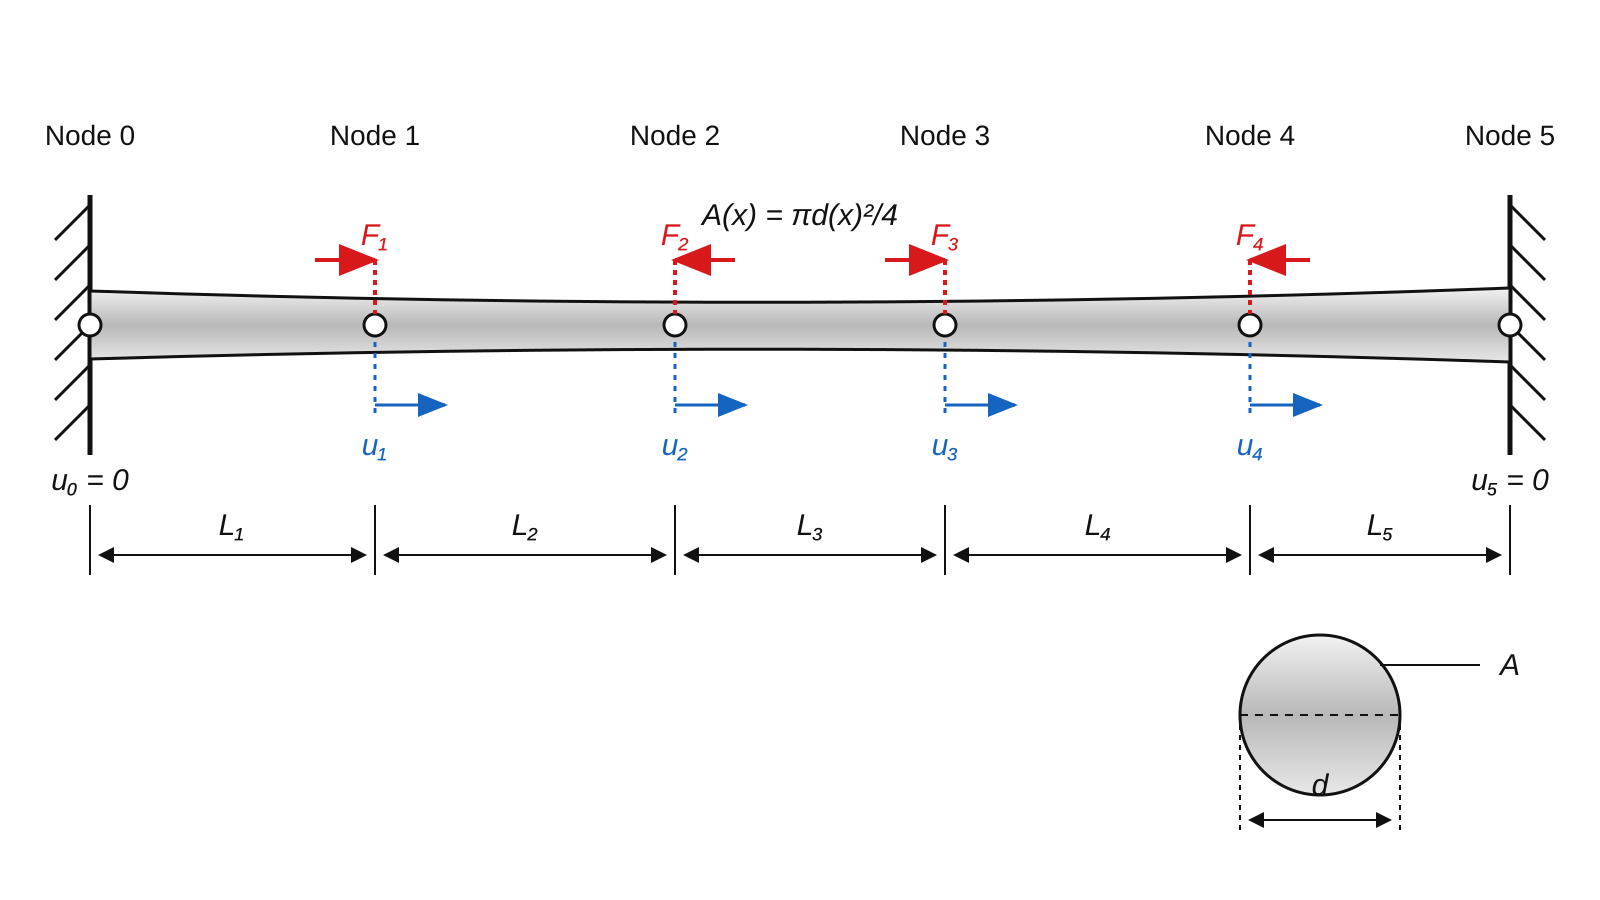

The goal of this problem is to determine the internal displacements $u_1, u_2,u_3,u_4$.

**Equilibrium analysis to determine internal displacements**

We call the segment between node $e-1$ and $e$ element $e$. That is, the segment between node 0 and 1 is element 1. The internal axial force $N_e$ in element $e$ is 


$$N_e = k_e(u_e-u_{e-1}),$$


where $k_e$ is the equivalent axial stiffness. A positive $N_e$ means the segment is stretched (in tension) and a negative $N_e$ means it is compressed. You can interpret this formula as Hooke's law written in terms of the two nodal displacements that bound the element — exactly like a spring of stiffness $k_e$ connecting node $e-1$to node $e$.

For a single node $i$, sitting between element $i$ on its left and $i+1$ on its right. Physically, a stretched segment pulls its two end‑nodes towards each other:

- Element $i$, if in tension, pulls node $i$ backward (toward node $i-1$) with magnitude $N_i$.

- Element $i+1$, if in tension, pulls node $i$ forward (toward node $i+1$) with magnitude $N_{i+1}$�.

Since all nodes are in a static equilibrium, the externally applied force $F_i$ must balance the net pull from the two segments:

$F_i = N_i-N_{i+1}$�

These equations allow you to determine the displacements.

**Plan**

Some of the data you need to determine the displacements is provided, other data you will have to determine empirically using measured data from the workbook *`stepped_bar_measurements.xlsx`.*

We will undertake the following steps

a. **Geometry characterization:** Determining the bar's geometry based on measurements taken at various positions along its axis.

b. **Material characterization:** Determining characteristic parameters of the material using measured stress–strain data.

c. **Structural analysis:** Calculating segment stiffness, segment forces and segment stresses.

d. **Volume determination: **computing the total volume of the bar. 

#### Structural data

The node positions are


$$
 \mathbf x=[0.00,\ 0.40,\ 0.90,\ 1.35,\ 1.90,\ 2.50]\ \mathrm{m}.
$$


The main forces applied at nodes 1 through 4 are


$$
 \mathbf F=[35,\ -20,\ 45,\ -25]^T\ \mathrm{kN}.
$$


#### Symbols

### Problem 1a. Geometry characterization (7 pts)

i) The bar diameter is represented by the single continuous polynomial $d(x)=a_0+a_1x+a_2x^2$. Determine the least squares fit to the data presented in the *`diameter_measurements' *worksheet of the workbook *`stepped_bar_measurements.xlsx`*. Plot the datapoints and fitted curve.

ii) Use the empirical bar diameter to calculate the circular cross-section area. Plot the area

$A(x)=\frac{\pi}{4}[d(x)]^2$.

Convert $d(x)$ from $\mathrm{mm}$ to $\mathrm{m}$ before calculating area in $\textrm{m}^2$.

iii) For the discrete structural model, the area of element $e$ is evaluated at its midpoint $\bar{x}_e=(x_{e-1}+x_e)/2$:


$$A_e=A(\bar{x}_e)=\frac{\pi}{4}[d(\bar{x}_e)]^2.$$


Compute the area of each of the elements.

# Solution 1a

### Problem 1b. Material characterization  (10 pts)

i) The relationship between axial strain and stress can be described by the nonlinear relationship

$  $$\sigma=K\varepsilon^n$$$,

where $K>0$ and $n$ are unknown. Determine estimates for the parameters $K$ and $n$ using a linear least squares fit. The data to fit to can be found in the *`power_law_test` *worksheet of the workbook *`stepped_bar_measurements.xlsx`*. Plot the datapoints and fitted curve.

ii) The fitted relationship is nonlinear, but the required structural system is linear. A tangent modulus is therefore evaluated at a selected reference strain:


$$E_{\mathrm{eq}}
 =\left.\frac{d\sigma}{d\varepsilon}\right|_{\varepsilon_{\mathrm{ref}}}
 =Kn\varepsilon_{\mathrm{ref}}^{n-1}$$


Use the reference strain


$$\varepsilon_{\mathrm{ref}}=0.010$$


Determine the equivalent tangent modulus based on your fit of the stress-strain relationship. Ensure consistent units are used.

iii) Finally, calculate the element stiffness for each element using the formula

$k_e=\frac{E_{\mathrm{eq}}A_e}{L_e}$.

# Solution 1b

### Problem 1c. Structural analysis  (20 pts)

i) Use the equilibrium analysis to determine internal displacements at the top of the problem to determine four equations for our four unknown internal-node displacements. The equations should be in terms of the element stiffnesses and the applied forces. The resulting linear system of equations should be of the form


$$\mathbf K\mathbf u=\mathbf F$$


where $\mathbf{K}$ is a symmetric $4\times 4$ matrix with positive diagonal entries. 

ii) Solve the system with a direct solver, Jacobi, and Gauss-Seidel. Specify which direct method you used and why. Compare the convergence behaviour of either iterative method and compare the convergence behaviour with the theoretical rates of convergence. Which of the three methods (direct, Jacobi, Gauss-Seidel) would you prefer to solve this system?

iii) For each segment, calculate the axial strain using

$\varepsilon_e=\frac{\delta_e}{L_e}$, where $\delta_e=u_e-u_{e-1}$, 

Two stress evaluations must be clearly distinguished:

1. the stress consistent with the equivalent linear structural solve,


$$  $$\sigma_{e,\mathrm{eq}}=E_{\mathrm{eq}}\varepsilon_e$$$$


2. the stress predicted by the fitted nonlinear material relationship,

$$$\sigma_{e,\mathrm{nl}}=K\,{\mathrm{sgn}}(\varepsilon_e)|\varepsilon_e|^n$$$.

Then calculate the corresponding internal axial force consistently as


$$N_e=A_e\sigma_e
$$


iv) Finally, classify each element as tension when $$\varepsilon_e>0$$**, **compression when $$\varepsilon_e<0$$, or zero response when the strain is numerically zero.

# Solution 1c

### Problem 1d. Volume determination (8 pts)

The total volume of the bar is

$V=\int_0^{2.5}A(x)\,dx$.

Use the empirical expression for the cross-sectional area from part 1a to compute the total volume of the bar. First, compute the integral analytically. Next, use the three Newton-Cotes rules discussed in class to approximate the integral. For each of the rules, analyse how quickly the errors decrease as the number of function evaluations is increased. Which of the rules do you prefer here?

# Solution 1d

## Problem 2: Numerical Analysis of a Hydrodynamic Slider Bearing (30 pts)

## What is a hydrodynamic bearing?

A hydrodynamic bearing is a machine element in which two solid surfaces are completely separated by a thin film of lubricant. When one surface moves relative to the other, it drags oil into a converging gap and generates a pressure distribution within the fluid. This pressure supports the applied mechanical load while preventing direct solid-to-solid contact, thereby reducing friction and wear. Unlike a hydrostatic bearing, a hydrodynamic bearing does not require an external pump to generate the supporting pressure; the pressure is produced by the relative motion and geometry of the surfaces.

The following schematic provides a reference for the bearing geometry, lubricant motion, generated pressure distribution, and resultant load:

Hydrodynamic slider bearing with a converging oil film. The moving surface drags lubricant from the larger inlet gap $$h_1$$ toward the smaller outlet gap $$h_2$
$, generating the pressure distribution $$p(x)$$.

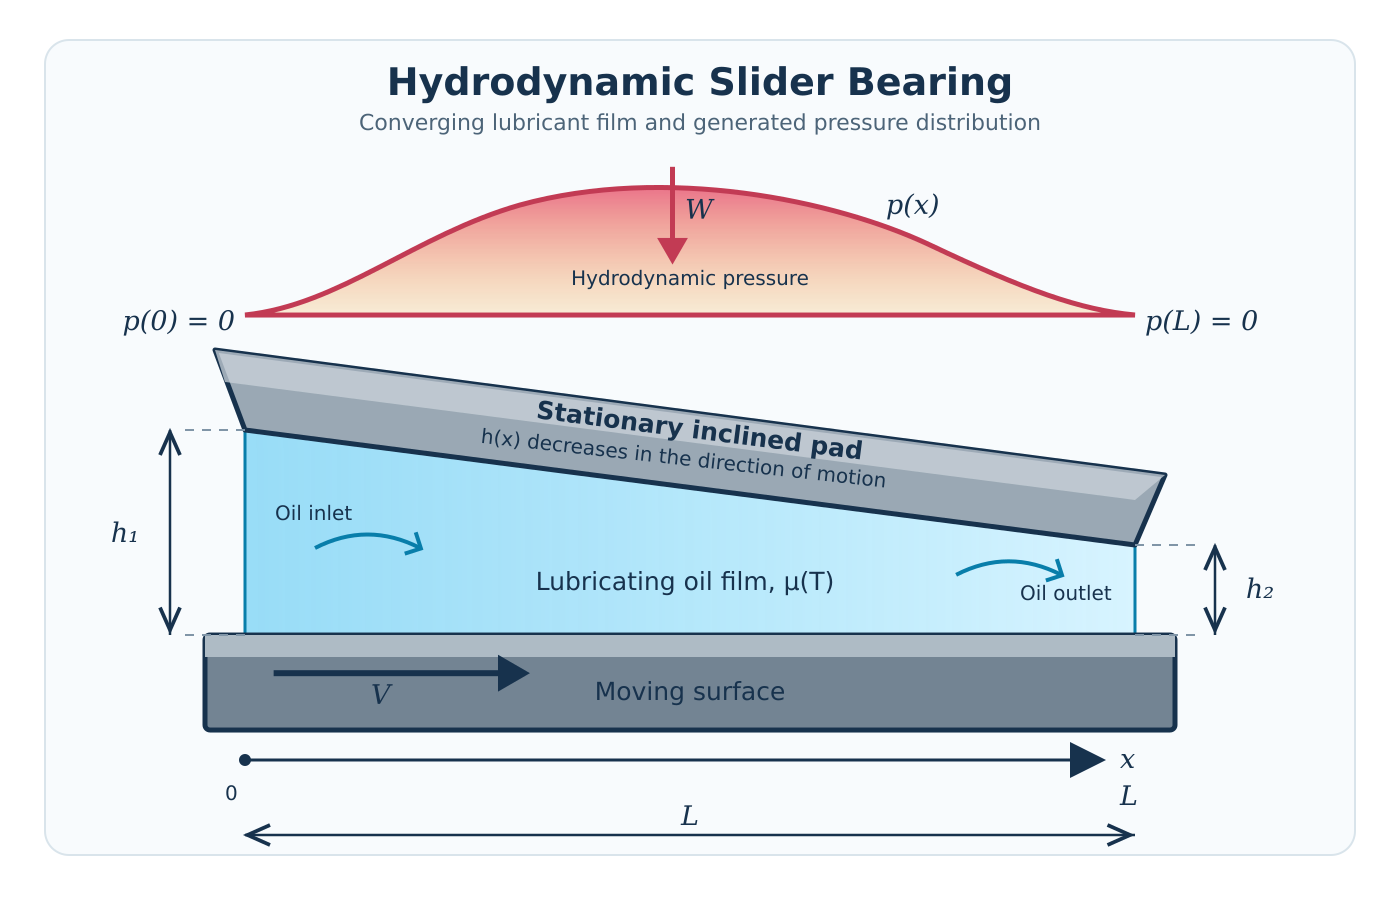

## Problem description

A hydrodynamic slider bearing consists of a stationary inclined pad and a flat moving surface separated by a thin film of lubricating oil. The lower surface moves with velocity $V$, dragging lubricant into the converging gap. The resulting pressure distribution allows the bearing to support a normal mechanical load.

In this project, experimental viscosity data will first be used to determine a temperature-dependent viscosity model. Experimental pressure measurements will then be used to describe the pressure distribution along the bearing. A physically constrained polynomial approximation will provide a smooth pressure curve and an estimate of the maximum pressure. Finally, Newton–Cotes formulas will be used to estimate the total load carried by the bearing and its effective position.

Considering this and the figure, we will determine:

a. The viscosity of the oil at operating temperature. 

b. The polynomial approximation of the pressure distribution. 

c. The maximum pressure and its position. 

d. The bearing's load-carrying capacity. 

Use the following data:

**Note: **$ $b$
$**is the bearing dimension perpendicular to the plane shown in the figure.**

The film thickness varies linearly along the bearing:


$$
 h(x)=h_1+\frac{h_2-h_1}{L}x,
 \qquad 0\leq x\leq L
$$


Pressure is measured relative to ambient pressure. The measurements at the inlet and outlet therefore satisfy


$$
 p(0)=0,
 \qquad
 p(L)=0
$$


Assume the nonlinear viscosity model


$$
 \mu(T)=A\exp\left(\frac{B}{T}\right)
$$


where $A$ and $B$ are unknown parameters.

### Problem 2a. Estimate viscosity of the oil (6 pts)

The experimental measurements are provided in the external workbook *`bearing_viscosity_measurements.xlsx`. *The worksheet *`viscosity_measurements`* contains 25 measurements and the columns *`temperature_C`, `temperature_K`, and `viscosity_Pa_s*`.

Before fitting the model, verify that all required columns exist, that the data contain no missing or non-finite entries, and that all Kelvin temperatures and viscosity measurements are positive. The temperature used in the viscosity model must always be expressed in kelvin.

Estimate the parameters in the nonlinear viscosity model using linear least squares. Plot the datapoints and the fitted model. What is the viscosity of the oil at the operating temperature?

# Solution 2a

### Problem 2b. The polynomial approximation of the pressure distribution (12 pts)

The worksheet `pressure_measurements` in the same Excel workbook contains 13 measurements and the columns `measurement_id`, `position_m`, and `pressure_Pa`.

First, compute the polynomial **interpolation** to all datapoints. 

Next, use linear least squares fitting to approximate the coefficients in the model

$
  p(s)=s(1-s)\left(c_0+c_1s+c_2s^2\right)
 }.
$, where $
 s=\frac{x}{L},
 \qquad 0\leq s\leq1$.

Note this is a fourth-degree polynomial, but with particular form to ensure the pressure is zero at either endpoint. Be specific about the design matrix and vector.

Plot both models together with the datapoints and comment on either model.

# Solution 2b

### Problem 2c. The maximum pressure and its position (4 pts)

Using your degree 4 polynomial approximation, determine the maximum pressure and the point at which the maximum pressure is attained.

# Solution 2c

### Problem 2d. The bearing's load-carrying capacity (8 pts)

The pressure produces a normal force on the pad. The total load carried by the bearing is


$$
  W=b\int_0^L p(x)\,dx
 $$


Again use the degree 4 polynomial approximation for $p(x)$. Determine the total load using the composite midpoint rule, the composite trapezoidal rule, and the composite Simpson's $\frac{1}{3}$ rule. Compare against the analytical value of the integral. For each of the rules, analyse how quickly the errors decrease as the number of function evaluations is increased. Which of the rules do you prefer here?

# Solution 2d